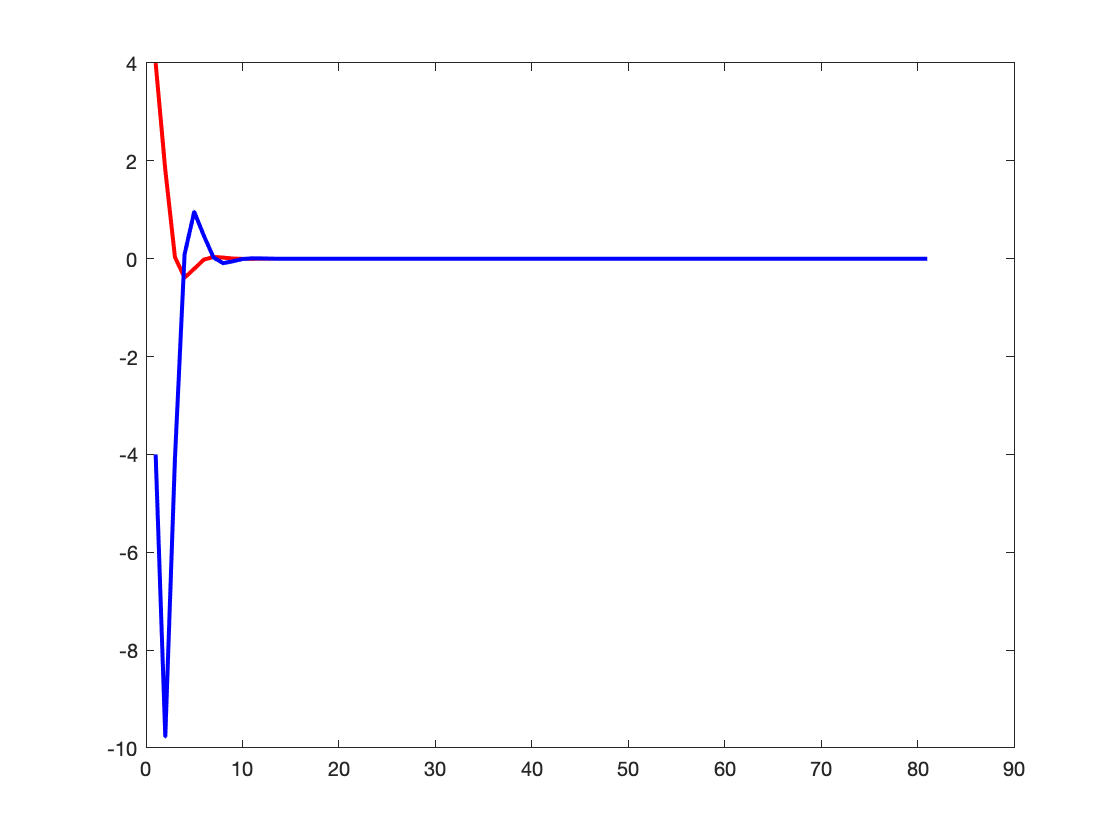

Foi possível calcular a solução exata!


syms u(t) v(t)


s1 = v;
s2 = -6*v-25*u;
f = @(t,u,v) eval(vectorize(s1));
g = @(t,u,v) eval(vectorize(s2));

u0 = 4;
v0 = -4;

a = 0;
b = 20;
n = 80;

try
    S = dsolve(diff(u) == f(t,u,v), diff(v) == g(t,u,v), u(0) == u0, v(0) == v0);
    if(isempty(S))
        error(S);
    end
    p = @(t) eval(vectorize(char(S.u)));
    k = @(t) eval(vectorize(char(S.v)));
    
    h = (b-a)/n;
    t = a:h:b;
    
    yExataU = p(t);
    yExataV = k(t);
    
    plot(yExataU,'-r','LineWidth',2);
    hold('on');
    plot(yExataV,'-b','LineWidth',2);
    hold('on');
    disp("Foi possível calcular a solução exata!")
catch
    disp("A solução exata não pôde ser calculada")
end




%syms u(t) v(t)

% s1 = 3*u + 4*v;
% s2 = -4*u + 3*v;
% f = @(t,u,v) eval(vectorize(s1));
% g = @(t,u,v) eval(vectorize(s2));
% u0 = 0;
% v0 = 1;
% 
% S = dsolve(diff(u) == f(t,u,v), diff(v) == g(t,u,v), u(0) == u0, v(0) == v0)
% yExataU = S.u;
% yExataV = S.v;
% 
% fplot(yExataU,'-r','LineWidth',2);
% hold('on');
% fplot(yExataV,'-b','LineWidth',2);
% hold('on');

